**Challenge Problem 1.1**

a = linspace(1,4,20)

a =     1.0000    1.1579    1.3158    1.4737    1.6316    1.7895    1.9474    2.1053    2.2632    2.4211    2.5789    2.7368    2.8947    3.0526    3.2105    3.3684    3.5263    3.6842    3.8421    4.0000


x = linspace(0,1,20)

x =          0    0.0526    0.1053    0.1579    0.2105    0.2632    0.3158    0.3684    0.4211    0.4737    0.5263    0.5789    0.6316    0.6842    0.7368    0.7895    0.8421    0.8947    0.9474    1.0000



f= @(a,x)(2./sqrt(2*(a.^4-x.^4)));

y= f(a,x)

y =     1.4142    1.0548    0.8169    0.6512    0.5313    0.4417    0.3731    0.3192    0.2763    0.2414    0.2128    0.1890    0.1690    0.1520    0.1374    0.1248    0.1139    0.1044    0.0960    0.0886



b=[];
for i=1:length(a)
    b(i) = trapz(a(i), y);
end

b

b =     6.7566    7.8234    8.8903    9.9571   11.0239   12.0907   13.1576   14.2244   15.2912   16.3581   17.4249   18.4917   19.5586   20.6254   21.6922   22.7591   23.8259   24.8927   25.9595   27.0264


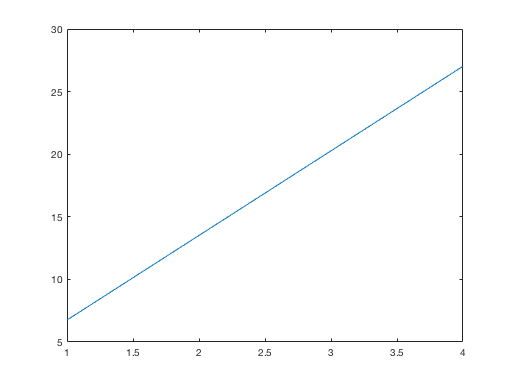


plot(a,b)